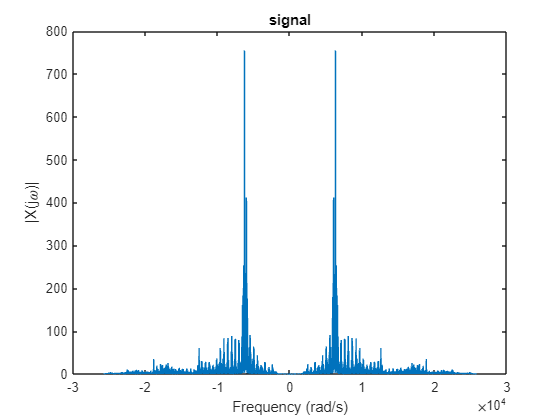

clear
% Load Signal 
load long_modem_rx.mat

% offset by the length of x_sync to only include the signal
start_idx = find_start_of_signal(y_r,x_sync);

% y_t is the signal which starts at the beginning of the transmission
y_t = y_r(start_idx+length(x_sync):end);

c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
%plot(t, cos_c)


%% Decoder Starts

%soundsc(y_t, Fs)
plot_ft_rad(y_t, Fs);
title('Signal');

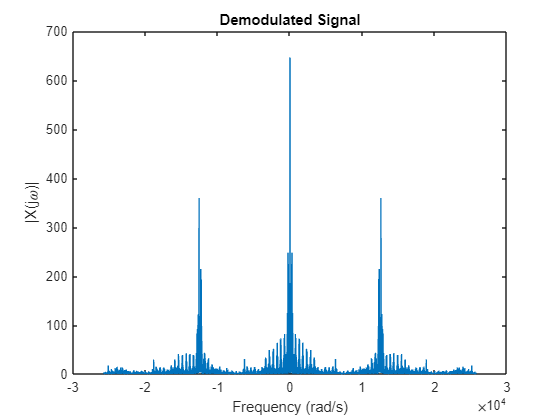

new_y = y_t.*c;
%soundsc(new_y, Fs)

plot_ft_rad(new_y, Fs);
title('Demodulated Signal');

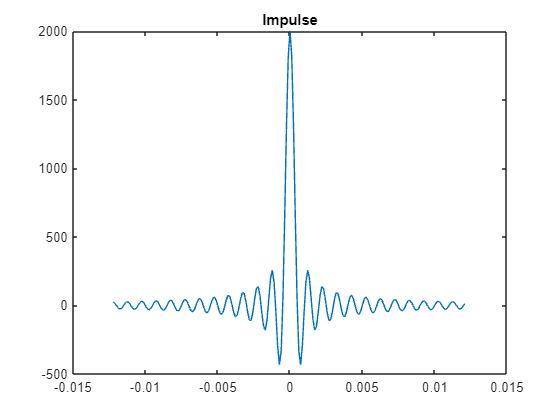


%Set the cutoff frequency for the low-pass filter
cutoff = 2*pi*f_c; 


%Setup Low Pass Filter%
W = cutoff;	% set the cutoff frequency to 2 pi * 1000 rads/s
t = [-100:1:99]*(1/Fs);   % create a 200 sample time vector to generate sinc
h = W/pi*sinc(W/pi*t);   % this is the impulse response
plot(t, h);   	% plot h to visualize
title('Impulse')

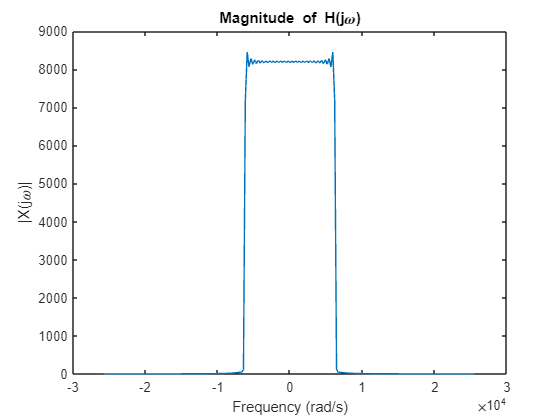


figure
plot_ft_rad(h, Fs);  % Visualize |H(j\omega)|
title('Magnitude of H(j\omega)');

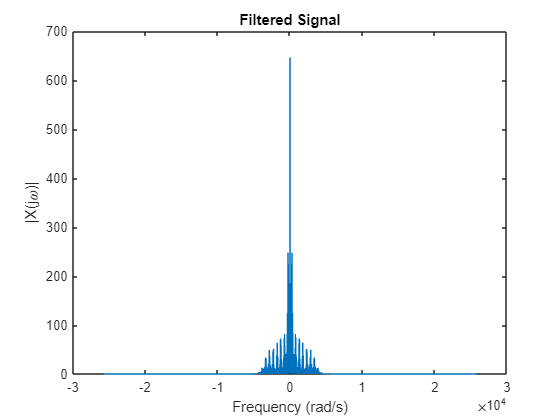

 
%filtered_y = conv(new_y, h);     % convolve x with h to filter the noise

%  Butter low-pass filter
%[b, a] = butter(6, f_c/(Fs/2));  % 6th order Butterworth filter
[b, a] = butter(12, 0.165);  % 12th order Butterworth filter

% Apply the filter using filtfilt to avoid phase distortion
filtered_y = filtfilt(b, a, new_y);

% Visualize the filtered signal in the frequency domain
figure;
plot_ft_rad(filtered_y, Fs);
title('Filtered Signal');


% Listen to the filtered signal to assess quality
%soundsc(filtered_y, Fs);

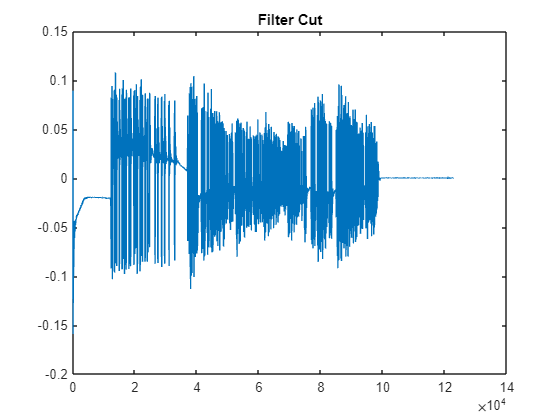

% Cut Specific Range Desired
filtered_cut_y = filtered_y;
y_square = filtered_cut_y;

%  Save Data in Binary
y_square(y_square > 0) = 1;
y_square(y_square < 0) = 0;

% Plot Filtered Signal in Desired Range
plot(filtered_cut_y);
title('Filter Cut');

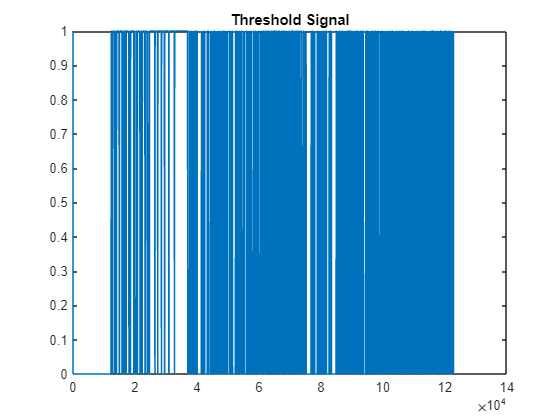


% Plot the thresholded signal
plot(y_square);
title('Threshold Signal');

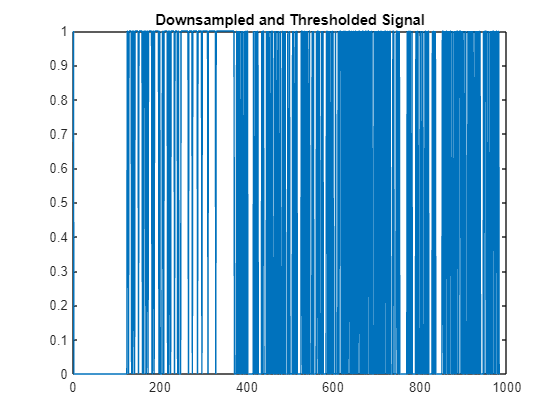


% Downsampling correctly based on SymbolPeriod
downsampled_y_square = downsample(y_square, 100);
downsampled_y_square = downsampled_y_square(1:8*msg_length);

% Plot to check the processed signal
plot(downsampled_y_square);
title('Downsampled and Thresholded Signal');

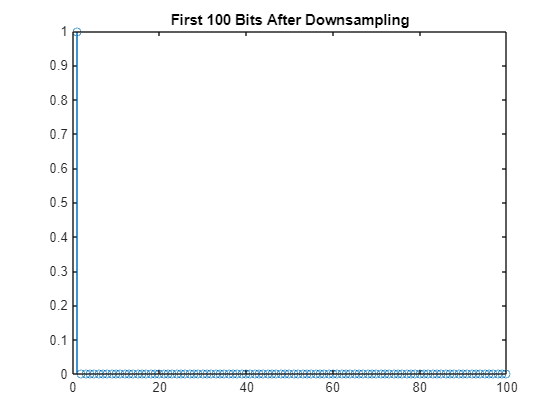


% Check downsampling result
figure;
stem(downsampled_y_square(1:100));  % Visualize the first 100 bits
title('First 100 Bits After Downsampling');


% Check length before conversion
disp(['Length of downsampled signal: ', num2str(length(downsampled_y_square))]);

Length of downsampled signal: 984



% Convert to string
decoded_message = BitsToString(downsampled_y_square);
disp(['Decoded Message: ', decoded_message]);

Decoded Message: □The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ..
